# Figure S1I

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files\F019_data\Data\Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
         'NR75 siCtrl DMSO',2:3,1:2,1:25,[0 0 0],[0 10]; %1    
         'NR75 siCtrl DOX',2:3,3:4,1:25,[0 0 0],[0 10]; %1    
         'NR75 siEmi1 DMSO',2:3,5:6,1:25,[0 0 0],[0 10]; %1    
         'NR75 siEmi1 DOX',2:3,7:8,1:25,[0 0 0],[0 10]; %1 
         'NR75 siTICRR DMSO',2:3,9:10,1:25,[0 0 0],[0 10]; %1    
         'NR75 siTICRR DOX',2:3,11:12,1:25,[0 0 0],[0 10]; %1

         'NR76 siCtrl DMSO',4:5,1:2,1:25,[0 0 0],[0 10]; %1    
         'NR76 siCtrl DOX',4:5,3:4,1:25,[0 0 0],[0 10]; %1    
         'NR76 siEmi1 DMSO',4:5,5:6,1:25,[0 0 0],[0 10]; %1    
         'NR76 siEmi1 DOX',4:5,7:8,1:25,[0 0 0],[0 10]; %1 
         'NR76 siTICRR DMSO',4:5,9:10,1:25,[0 0 0],[0 10]; %1    
         'NR76 siTICRR DOX',4:5,11:12,1:25,[0 0 0],[0 10]; %1
         
         'NR77 siCtrl DMSO',6:7,1:2,1:25,[0 0 0],[0 10]; %1    
         'NR77 siCtrl DOX',6:7,3:4,1:25,[0 0 0],[0 10]; %1    
         'NR77 siEmi1 DMSO',6:7,5:6,1:25,[0 0 0],[0 10]; %1    
         'NR77 siEmi1 DOX',6:7,7:8,1:25,[0 0 0],[0 10]; %1 
         'NR77 siTICRR DMSO',6:7,9:10,1:25,[0 0 0],[0 10]; %1    
         'NR77 siTICRR DOX',6:7,11:12,1:25,[0 0 0],[0 10]; %1
    };


% load([dataDir 'sensordata.mat'],'S');
S = loadData_IF(conditions, dataDir);

**Compare histograms of EdU no gate**

conds = [1 3];
cols =  [0 0 .5;.4 .7 0;.941 .447 .282];
yval = 'YFP1';

gateVals = {};
rangeVals = {[2^5 2^11]}; 

figure('unit','inches','position',[0 0 6 6]),

% axes('units','inches','position',[2 2 3 3])
hold on

hold on
for i = 1:length(conds)
    condition = conds(i);
    ydata = log2(S(condition).(yval)); %.*S(condition).area);

    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    sum(totalGate)
    ydata = ydata(totalGate);
    edges = linspace(4,12,100);
    
    [N,~] = histcounts(ydata,edges);
   plot(edges(2:end),N/length(ydata),'Linewidth',2,'color',cols(i,:));

end

ans = 34553

ans = 30168

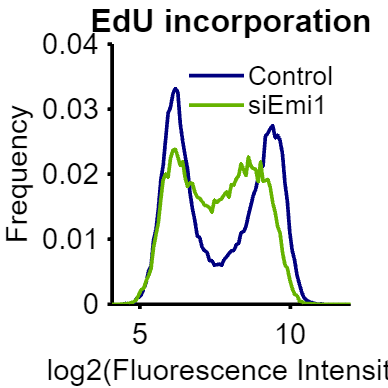

 % 
set(gca,'fontsize',16,'linewidth',2)
legend('Control','siEmi1','box','off');
xlabel('log2(Fluorescence Intensity)')
ylabel ('Frequency')
hold off
title('EdU incorporation')
set(gca,'FontSize',16)

 % print_pdf(['fig_S1I.pdf'])